*This is the real time script of tremor analysis for better visualization.

**Read in the trc data**

data = read_trc("deidentified_trc/688/sit-rest1-TP.trc");
% Peek the first five rows of the table
head(data, 5)

ans = 5×182 table
    Frame#    Time     Top.Head     Var4      Var5     Front.Head     Var7      Var8     Rear.Head    Var10     Var11       Jaw      Var13     Var14       C7       Var16     Var17     R.Clavicle    Var19     Var20     L.Clavicle    Var22     Var23     R.Shoulder     Var25     Var26     L.Shoulder    Var28     Var29     R.Scapula    Var31     Var32     L.Scapula    Var34     Var35     

trc = rename_trc(data);
% Obderve the table after renaming
head(trc, 1)

ans = 1×182 table
    Frame#    Time    Top.Head_X    Top.Head_Y    Top.Head_Z    Front.Head_X    Front.Head_Y    Front.Head_Z    Rear.Head_X    Rear.Head_Y    Rear.Head_Z     Jaw_X     Jaw_Y    Jaw_Z      C7_X       C7_Y      C7_Z     R.Clavicle_X    R.Clavicle_Y    R.Clavicle_Z    L.Clavicle_X    L.Clavicle_Y    L.Clavicle_Z    R.Shoulder_X    R.Shoulder_Y    R.Shoulder_Z    L.Shoulder_X    L.Shoulder_Y    L.Shoulder_Z    R.Scapula_X    R.Scapula_Y    R.Scapu

**Filter data**

Only leave the data with the specific markername, and pass the data to a butterworth bandpass filter.

default_markername = "L.Finger3.M3";
% Filter out the unrelated markers
raw_data = trc{:,startsWith(names(trc),"L.Wrist")};
% View the first row of the data
disp(raw_data(1, :))

   31.3846  273.6948  641.1412



% Call the bandpass butterworth filter
filtered_data = preprocess_marker_data(raw_data,trc.Time, [2 45]);

**Principle component analysis**

% Both pc1_mm and time are 3600 x 1 vector
time_s = trc.Time;
pc1_mm = pc1(filtered_data);

Visualize the principle component vs. the time.

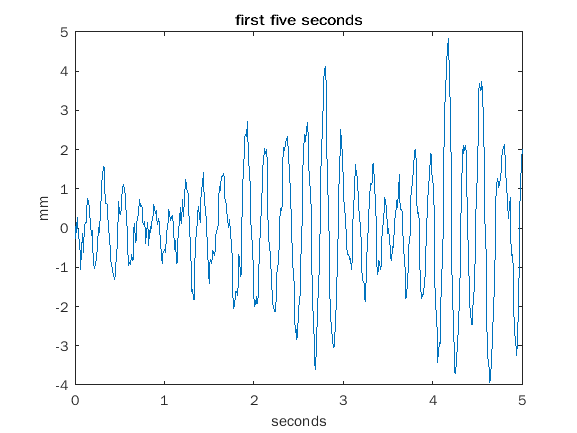

figure
plot(time_s, pc1_mm);
xlim([0, 5])
xlabel("seconds")
ylabel("mm")
title("first five seconds")

% save the figure
saveas(gcf, "figures/figure1.png")

**Visualizing time-varying tremor**

% Make the time table
TT=timetable(seconds(time_s),pc1_mm);
TT.Properties.VariableNames = ["L.Wrist"];
TT.Properties.VariableUnits = ["mm"];
% 3D visualization
[p,f,t] = pspectrum(TT, 'spectrogram', 'MinThreshold', -50, 'FrequencyResolution',0.5, 'FrequencyLimits',[0 20]);

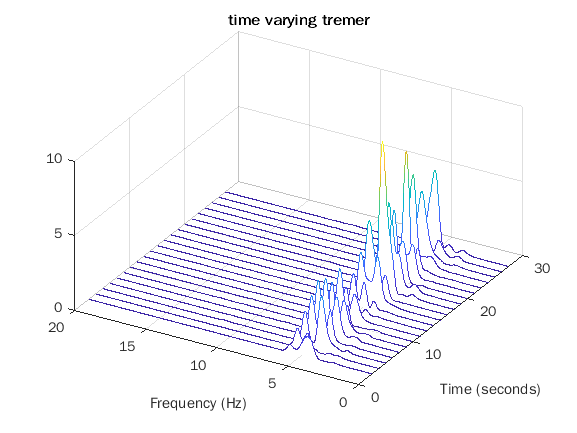

figure
waterfall(f, seconds(t), p')
xlabel("Frequency (Hz)")
ylabel("Time (seconds)")
wtf = gca;
wtf.XDir = "reverse";
view([30, 45])
title("time varying tremer")
saveas(gcf, "figures/figure2.png")

**Visualize the spectrogram over time**

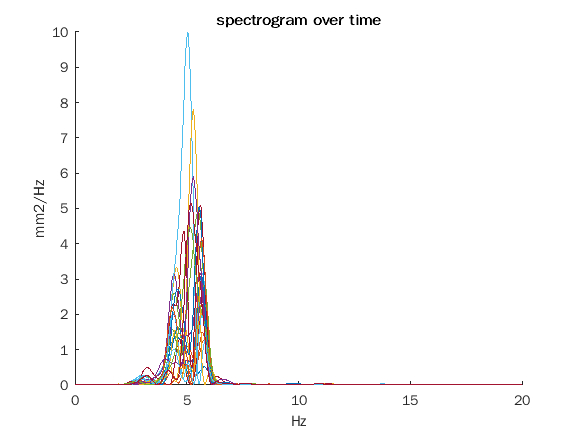

figure
hold on
for i = 1:size(p, 2)
    plot(f, p(:, i));
end
xlabel("Hz")
ylabel("mm2/Hz")
title("spectrogram over time")
saveas(gcf, "figures/figure3.png")
hold off

**Summarize the outcomes for the left wrist resting / action tremor**

% max power in any window (mm2/Hz)
[max_p, ind] = max(p, [], "all");
disp(["The max power in any window is:", max_p])

    "The max power in any window is:"    "9.9794"



% Maximum power in any window
[r_ind,~] = ind2sub(size(p),ind);
f_max_p = f(r_ind);
disp(["The freuncy at overall max power:", f_max_p])

    "The freuncy at overall max power:"    "5.04"



% variability in peak frequency, Hz
[~,ind] = max(p,[],1); 
f_sd = std(f(ind));
disp(["Standard deviation in peak frequency", f_sd])

    "Standard deviation in peak frequency"    "0.36709"



% find the window number of the maximum power
[~, c_ind] = find(p == max_p);
%find the rms near the overall power
rms_power = rms(p(f-f_max_p<0.5 & f-f_max_p>-0.5, c_ind));
disp(["RMS Power", rms_power])

    "RMS Power"    "6.7346"

